# ME441-001 Final Project

## Daniel Waggner + Corbin Strycker

Problem DFN:

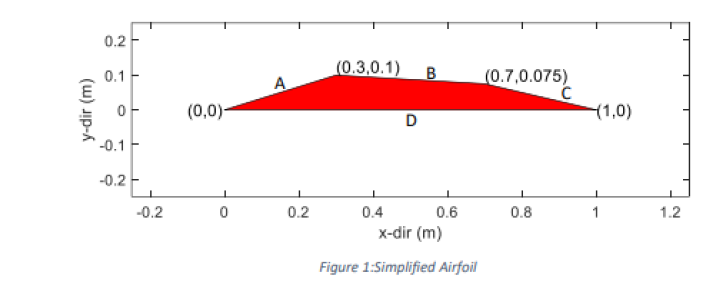

Initial CMDs

clear; 
clc;
close all;
format short;

Data

% Angle of Attack
alpha = 10;
% Requested Mach Number(s)
M1Init = 3.0; 

Variable DFNs

% Flow Vector
flowVectorMag = 0.35;
flowVectorPosx = -1 * flowVectorMag * cosd(alpha);
flowVectorPosy = flowVectorMag * sind(alpha); 

xvalstop = [flowVectorPosx, 0, 0.3, 0.7, 1.0];
yvalstop = [flowVectorPosy, 0, 0.1, 0.075, 0];

xvalsbottom = [flowVectorPosx, 0, 1.0];
yvalsbottom = [flowVectorPosy, 0, 0];

Assumptions:

    1. Acting Fluid is Air modeled as a callorically perfect gas

    2. Frictionless Flow (Inviscid)

    3. Fluid is Air @ STP

gamma = 1.4;
R = 287; % J/kg-K
T_flow_abs = 20+273; % k
P_flow = 101325; % Pa
rho_flow = 1.21; % kg/m^3

Plots

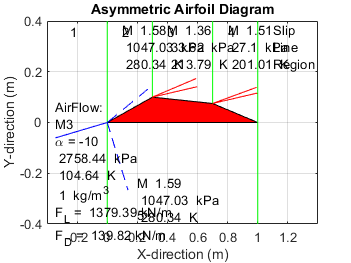

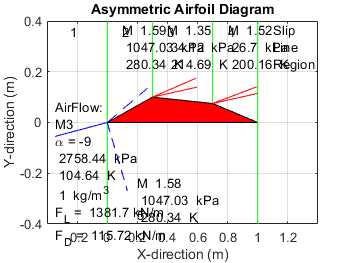

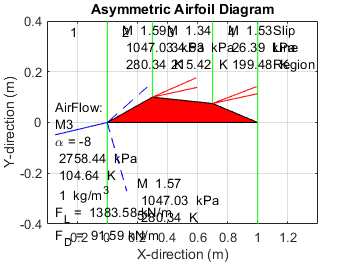

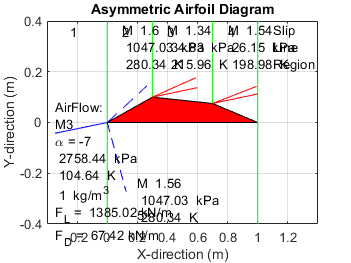

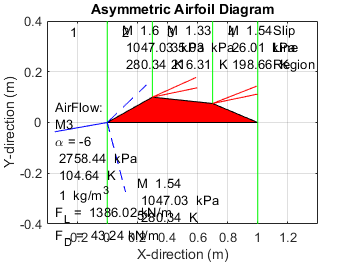

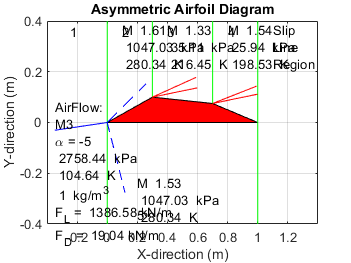

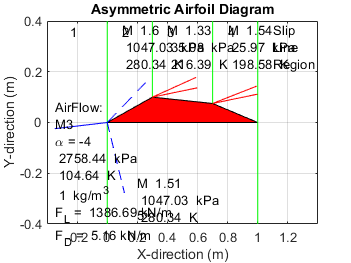

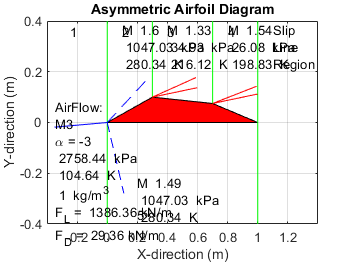


% alpha = 10;
% figure(1);
% hold on;
% [Flift, Fdrag] = ...
%     airfoilPropertiesPlotter(P_flow,T_flow_abs,...
%     M1Init, xvalstop, yvalstop, xvalsbottom, yvalsbottom, alpha,...
%     rho_flow, gamma, flowVectorPosx, flowVectorPosy, R);
% fprintf("Lift and Drag  %4.2f kN/m and %4.2f kN/m", ...
%         Flift, Fdrag);
% hold off;
% pause(10);
% 
% alpha = 10;
% figure(2);
% hold on;
% [Flift, Fdrag] = ...
%     airfoilPropertiesPlotter(P_flow,T_flow_abs,...
%     M1Init, xvalstop, yvalstop, xvalsbottom, yvalsbottom, alpha,...
%     rho_flow, gamma, flowVectorPosx, flowVectorPosy, R);
% fprintf("Lift and Drag  %4.2f kN/m and %4.2f kN/m", ...
%         Flift, Fdrag);
% hold off;
% pause(10);


%Varying Alpha
alpha = -10:1:10; 
k = 1;
while k <= length(alpha)
    fig = figure("Resize","off");
    hold on;
    flowVectorMag = 0.35;
    flowVectorPosx = -1 * flowVectorMag * cosd(alpha(k));
    flowVectorPosy = flowVectorMag * sind(alpha(k));
    xvalstop = [flowVectorPosx, 0, 0.3, 0.7, 1.0];
    yvalstop = [flowVectorPosy, 0, 0.1, 0.075, 0];

    xvalsbottom = [flowVectorPosx, 0, 1.0];
    yvalsbottom = [flowVectorPosy, 0, 0];
    [Flift, Fdrag] = ...
        airfoilPropertiesPlotter(P_flow,T_flow_abs,...
        M1Init, xvalstop, yvalstop, xvalsbottom,...
        yvalsbottom, alpha(k),rho_flow, gamma,...
        flowVectorPosx, flowVectorPosy, R);
%         fprintf("Lift and Drag  %4.2f kN/m and %4.2f kN/m", ...
%         Flift, Fdrag);
        FL(k) = Flift;
        FD(k) = Fdrag;
        pause(.5);
        hold off;
        frame(k) = getframe(fig);
        k = k + 1;
end


%Uncomment out the code or copy it into the console
%   to view the animation (my PC cannot deal with
%   trying to run the script and then play the
%   animation

%       movie(frame, 20)

%   salesartillery.com/fs/top-100-aerospace-companies
%   usajobs